DB_DATA


PCA_DATA


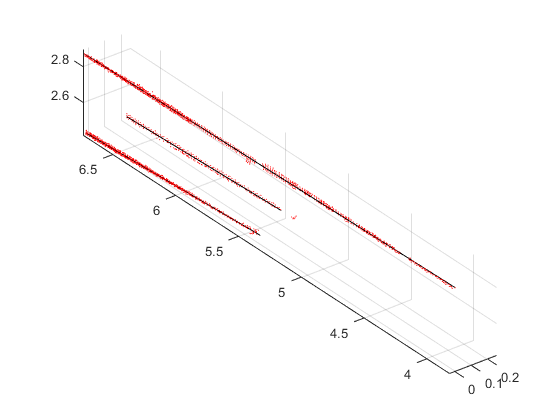

clc;clear all;close all;


fprintf('DB_DATA\r\n');
cla_data = open_and_importdata('G:\論文\1080919\FULL\20210415\20210501');
fprintf('PCA_DATA\r\n');
pca_data = open_and_importdata('G:\論文\1080919\FULL\20210415\20210501');

%B1=5,B2=17.5,B4=42.5,B6=67.5,M=130,T6=192.5,T4=217.5,T2=242.5,T1=255

group_num = 1;

figure(1)
scatter3(pca_data(:,1),pca_data(:,2),pca_data(:,3),1,'r','filled');hold on
axis equal

%% B14,B16

% start=zeros(4,3);
% start(:,2)=0.08;
% 
% B1=zeros(4,3);
% B1(:,2)=0.885;
% 
% B2=zeros(4,3);
% B2(:,2)=1.69;
% 
% B3=zeros(4,3);
% B3(:,2)=2.495;
% 
% Bot=zeros(4,3);
% Bot(:,2)=3.33;
% 
% cla_data_Y = cla_data(find(cla_data(:,4)==2),:);
% 
% group_num = max(cla_data_Y(:,5));
% group_mean=zeros(group_num,4);
% for i=1:group_num
%     samegroup = find(cla_data_Y(:,5)==i);
%     for j=1:size(samegroup)
%         cla_data_Y(samegroup(j),6)=group_mean(i,1);
%     end
% end
% 
% if cla_data(:,4)==2
%     new_group=[];
%     for i=1:max(cla_data_Y(:,5))
%         new_group_num = find(cla_data_Y(:,5)==i);
%         if size(new_group_num)~=0
%             new_group(i,:) = cla_data_Y(new_group_num(1,1),:);
%         end
%     end
%     new_group(all(new_group==0,2),:)=[];
%     for i=1:size(new_group)
%         new_group(i,6)=i;
%     end
%     new_group_data=[];
%     for i=1:size(new_group)
%         new_group_data = find(cla_data_Y(:,5)==new_group(i,5));
%         cla_data_Y(new_group_data(:,1),6)=new_group(i,6);
%     end
%     
%     for i=1:1:max(cla_data_Y(:,6))
%         group = [];
%         group = find(cla_data_Y(:,6)==i);
%         
%         x = cla_data_Y(group,1);
%         y = cla_data_Y(group,2);
%         z = cla_data_Y(group,3);
%         % 分別擬合兩個二維的曲線，然後統一到一起
%         p_yx = polyfit(y,x,1);
%         x_out = polyval(p_yx, y);
%         
%         start(i,1)=polyval(p_yx,start(i,2));
%         B1(i,1)=polyval(p_yx,B1(i,2));
%         B2(i,1)=polyval(p_yx,B2(i,2));
%         B3(i,1)=polyval(p_yx,B3(i,2));
%         Bot(i,1)=polyval(p_yx,Bot(i,2));
%         
%         p_yz = polyfit(y,z,1);
%         z_out = polyval(p_yz, y);
%         
%         start(i,3)=polyval(p_yz,start(i,2));
%         B1(i,3)=polyval(p_yz,B1(i,2));
%         B2(i,3)=polyval(p_yz,B2(i,2));
%         B3(i,3)=polyval(p_yz,B3(i,2));
%         Bot(i,3)=polyval(p_yz,Bot(i,2));
%         
%         % 得出曲線函數 x_out = f(z_out)   z_out = f(y)
%         p_zx_out = polyfit(z_out,x_out,1);
%         x_out_f = polyval(p_zx_out,z_out);
%         
%         start(i,1)=polyval(p_zx_out,start(i,3));
%         B1(i,1)=polyval(p_zx_out,B1(i,3));
%         B2(i,1)=polyval(p_zx_out,B2(i,3));
%         B3(i,1)=polyval(p_zx_out,B3(i,3));
%         Bot(i,1)=polyval(p_zx_out,Bot(i,3));
%         
%         group_num = group_num +1;
%         
%         figure(1)
%         plot3(x_out_f,y,z_out,'k'); hold on;
%     end
% end
% 
% DATA = [start;B1;B2;B3;Bot];
% xlswrite('F:\論文\1080919\FULL\20210415\20210501\B16\B16_0919_DATA_20210501.xlsx',DATA);


%% B15,B17

start=zeros(4,3);
start(:,2)=4.2;

B1=zeros(4,3);
B1(:,2)=5.025;

B2=zeros(4,3);
B2(:,2)=5.85;

B3=zeros(4,3);
B3(:,2)=6.675;

Bot=zeros(4,3);
Bot(:,2)=7.5;

cla_data_Y = cla_data(find(cla_data(:,4)==2),:);

group_num = max(cla_data_Y(:,5));
group_mean=zeros(group_num,4);
for i=1:group_num
    samegroup = find(cla_data_Y(:,5)==i);
    for j=1:size(samegroup)
        cla_data_Y(samegroup(j),6)=group_mean(i,1);
    end
end

if cla_data(:,4)==2
    new_group=[];
    for i=1:max(cla_data_Y(:,5))
        new_group_num = find(cla_data_Y(:,5)==i);
        if size(new_group_num)~=0
            new_group(i,:) = cla_data_Y(new_group_num(1,1),:);
        end
    end
    new_group(all(new_group==0,2),:)=[];
    for i=1:size(new_group)
        new_group(i,6)=i;
    end
    new_group_data=[];
    for i=1:size(new_group)
        new_group_data = find(cla_data_Y(:,5)==new_group(i,5));
        cla_data_Y(new_group_data(:,1),6)=new_group(i,6);
    end
    
    for i=1:1:max(cla_data_Y(:,6))
        group = [];
        group = find(cla_data_Y(:,6)==i);
        
        x = cla_data_Y(group,1);
        y = cla_data_Y(group,2);
        z = cla_data_Y(group,3);
        % 分別擬合兩個二維的曲線，然後統一到一起
        p_yx = polyfit(y,x,1);
        x_out = polyval(p_yx, y);
        
        start(i,1)=polyval(p_yx,start(i,2));
        B1(i,1)=polyval(p_yx,B1(i,2));
        B2(i,1)=polyval(p_yx,B2(i,2));
        B3(i,1)=polyval(p_yx,B3(i,2));
        Bot(i,1)=polyval(p_yx,Bot(i,2));
        
        p_yz = polyfit(y,z,1);
        z_out = polyval(p_yz, y);
        
        start(i,3)=polyval(p_yz,start(i,2));
        B1(i,3)=polyval(p_yz,B1(i,2));
        B2(i,3)=polyval(p_yz,B2(i,2));
        B3(i,3)=polyval(p_yz,B3(i,2));
        Bot(i,3)=polyval(p_yz,Bot(i,2));
        
        % 得出曲線函數 x_out = f(z_out)   z_out = f(y)
        p_zx_out = polyfit(z_out,x_out,1);
        x_out_f = polyval(p_zx_out,z_out);
        
        start(i,1)=polyval(p_zx_out,start(i,3));
        B1(i,1)=polyval(p_zx_out,B1(i,3));
        B2(i,1)=polyval(p_zx_out,B2(i,3));
        B3(i,1)=polyval(p_zx_out,B3(i,3));
        Bot(i,1)=polyval(p_zx_out,Bot(i,3));
        
        group_num = group_num +1;
        
        figure(1)
        plot3(x_out_f,y,z_out,'k'); hold on;
    end
end

DATA = [start;B1;B2;B3;Bot];
%%xlswrite('F:\論文\1080919\FULL\20210415\20210501\B15\B15_0919_DATA_20210501.xlsx',DATA);
